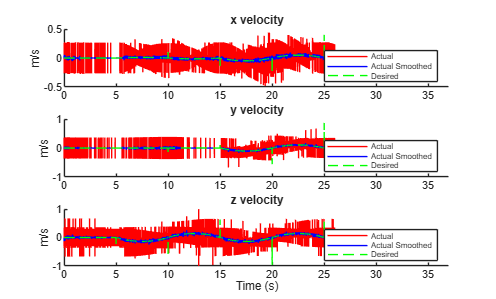

clc;
clear;
load("C:\Users\Antony\Documents\GitHub\ME423\Lab_4\positiondata.mat")
fontsiz = 6;
t = data(1,:);
dt = t(2) - t(1);

% Desired position
x_d = data(2,:);  y_d = data(3,:);  z_d = data(4,:);

% Actual position
x_a = data(5,:);  y_a = data(6,:);  z_a = data(7,:);

%% --- (Optional) smooth ONLY actual position before differentiating ---
% Small window is usually enough; increase if encoder noise is nasty
x_as = smoothdata(x_a,'gaussian',10);
y_as = smoothdata(y_a,'gaussian',10);
z_as = smoothdata(z_a,'gaussian',10);

%% --- VELOCITY ---
x_dot_d = [0 diff(x_d)/dt];
y_dot_d = [0 diff(y_d)/dt];
z_dot_d = [0 diff(z_d)/dt];

x_dot_a = [0 diff(x_a)/dt];
y_dot_a = [0 diff(y_a)/dt];
z_dot_a = [0 diff(z_a)/dt];

x_dot_as = [0 diff(x_as)/dt];
y_dot_as = [0 diff(y_as)/dt];
z_dot_as = [0 diff(z_as)/dt];

%% --- ACCELERATION ---
x_ddot_d = [0 diff(x_dot_d)/dt];
y_ddot_d = [0 diff(y_dot_d)/dt];
z_ddot_d = [0 diff(z_dot_d)/dt];

x_ddot_a = [0 diff(x_dot_a)/dt];
y_ddot_a = [0 diff(y_dot_a)/dt];
z_ddot_a = [0 diff(z_dot_a)/dt];

x_ddot_as = [0 diff(x_dot_as)/dt];
y_ddot_as = [0 diff(y_dot_as)/dt];
z_ddot_as = [0 diff(z_dot_as)/dt];

%% --- JERK ---
x_jerk_d = [0 diff(x_ddot_d)/dt];
y_jerk_d = [0 diff(y_ddot_d)/dt];
z_jerk_d = [0 diff(z_ddot_d)/dt];

x_jerk_a = [0 diff(x_ddot_a)/dt];
y_jerk_a = [0 diff(y_ddot_a)/dt];
z_jerk_a = [0 diff(z_ddot_a)/dt];

x_jerk_as = [0 diff(x_ddot_as)/dt];
y_jerk_as = [0 diff(y_ddot_as)/dt];
z_jerk_as = [0 diff(z_ddot_as)/dt];

%% --- PLOTS (Velocity) ---
figure();
subplot(3,1,1)
hold on;
plot(t, x_dot_a, "red","DisplayName","Actual")
plot(t, x_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, x_dot_d, "green","LineStyle","--","DisplayName","Desired")
title("x velocity")
ylabel("m/s")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, y_dot_a, "red","DisplayName","Actual")
plot(t, y_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, y_dot_d, "green","LineStyle","--","DisplayName","Desired")
title("y velocity")
ylabel("m/s")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, z_dot_a, "red","DisplayName","Actual")
plot(t, z_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, z_dot_d, "green","LineStyle","--","DisplayName","Desired")
title("z velocity")
ylabel("m/s")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

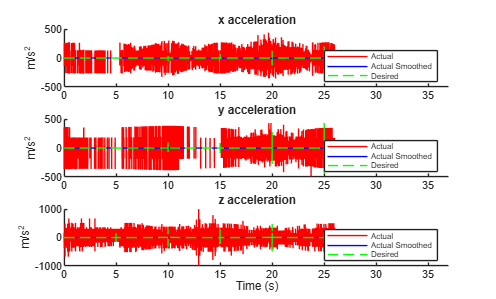



%% --- PLOTS (Acceleration) ---
figure();
subplot(3,1,1)
hold on;
plot(t, x_ddot_a, "red","DisplayName","Actual")
plot(t, x_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, x_ddot_d, "green","LineStyle","--","DisplayName","Desired")
title("x acceleration")
ylabel("m/s^2")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, y_ddot_a, "red","DisplayName","Actual")
plot(t, y_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, y_ddot_d, "green","LineStyle","--","DisplayName","Desired")
title("y acceleration")
ylabel("m/s^2")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, z_ddot_a, "red","DisplayName","Actual")
plot(t, z_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, z_ddot_d, "green","LineStyle","--","DisplayName","Desired")
title("z acceleration")
ylabel("m/s^2")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

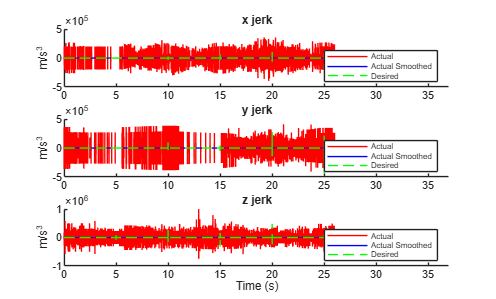


%% --- PLOTS (Jerk) ---
figure();
subplot(3,1,1)
hold on;
plot(t, x_jerk_a, "red","DisplayName","Actual ")
plot(t, x_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, x_jerk_d, "green","LineStyle","--","DisplayName","Desired")
title("x jerk")
ylabel("m/s^3")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize =fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, y_jerk_a, "red","DisplayName","Actual")
plot(t, y_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, y_jerk_d, "green","LineStyle","--","DisplayName","Desired")
title("y jerk")
ylabel("m/s^3")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, z_jerk_a, "red","DisplayName","Actual")
plot(t, z_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, z_jerk_d, "green","LineStyle","--","DisplayName","Desired")
title("z jerk")
ylabel("m/s^3")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

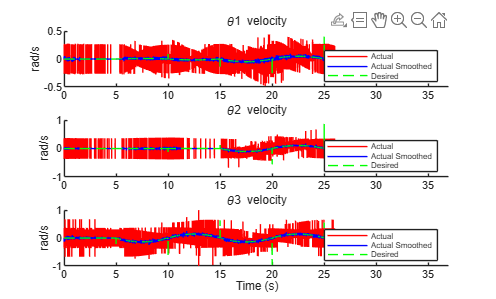

clc;
clear;
load("C:\Users\Antony\Documents\GitHub\ME423\Lab_4\positiondata.mat")
fontsiz = 6;
t = data(1,:);
dt = t(2) - t(1);

% Desired position
theta1_dot_d = data(2,:);  
theta2_dot_d = data(3,:);  
theta3_dot_d = data(4,:);

% Actual position
theta1_dot_a = data(5,:);  
theta2_dot_a = data(6,:);  
theta3_dot_a = data(7,:);

%% --- (Optional) smooth ONLY actual position before differentiating ---
% Small window is usually enough; increase if encoder noise is nasty
theta1_dot_as = smoothdata(theta1_dot_a,'gaussian',10);
theta2_dot_as = smoothdata(theta2_dot_a,'gaussian',10);
theta3_dot_as = smoothdata(theta3_dot_a,'gaussian',10);

%% --- VELOCITY ---
theta1_dot_dot_d = [0 diff(theta1_dot_d)/dt];
theta2_dot_dot_d = [0 diff(theta2_dot_d)/dt];
theta3_dot_dot_d = [0 diff(theta3_dot_d)/dt];

theta1_dot_dot_a = [0 diff(theta1_dot_a)/dt];
theta2_dot_dot_a = [0 diff(theta2_dot_a)/dt];
theta3_dot_dot_a = [0 diff(theta3_dot_a)/dt];

theta1_dot_dot_as = [0 diff(theta1_dot_as)/dt];
theta2_dot_dot_as = [0 diff(theta2_dot_as)/dt];
theta3_dot_dot_as = [0 diff(theta3_dot_as)/dt];

%% --- ACCELERATION ---
theta1_ddot_d = [0 diff(theta1_dot_dot_d)/dt];
theta2_ddot_d = [0 diff(theta2_dot_dot_d)/dt];
theta3_ddot_d = [0 diff(theta3_dot_dot_d)/dt];

theta1_ddot_a = [0 diff(theta1_dot_dot_a)/dt];
theta2_ddot_a = [0 diff(theta2_dot_dot_a)/dt];
theta3_ddot_a = [0 diff(theta3_dot_dot_a)/dt];

theta1_ddot_as = [0 diff(theta1_dot_dot_as)/dt];
theta2_ddot_as = [0 diff(theta2_dot_dot_as)/dt];
theta3_ddot_as = [0 diff(theta3_dot_dot_as)/dt];

% --- JERK ---
theta1_jerk_d = [0 diff(theta1_ddot_d)/dt];
theta2_jerk_d = [0 diff(theta2_ddot_d)/dt];
theta3_jerk_d = [0 diff(theta3_ddot_d)/dt];

theta1_jerk_a = [0 diff(theta1_ddot_a)/dt];
theta2_jerk_a = [0 diff(theta2_ddot_a)/dt];
theta3_jerk_a = [0 diff(theta3_ddot_a)/dt];

theta1_jerk_as = [0 diff(theta1_ddot_as)/dt];
theta2_jerk_as = [0 diff(theta2_ddot_as)/dt];
theta3_jerk_as = [0 diff(theta3_ddot_as)/dt];

%% --- PLOTS (Velocity) ---
figure();
subplot(3,1,1)
hold on;
plot(t, theta1_dot_dot_a, "red","DisplayName","Actual")
plot(t, theta1_dot_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta1_dot_dot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta1 velocity")
ylabel("rad/s")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, theta2_dot_dot_a, "red","DisplayName","Actual")
plot(t, theta2_dot_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta2_dot_dot_d, "green","LineStyle","--","DisplayName","Desired")
ylabel("rad/s")
subtitle("\theta2 velocity")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, theta3_dot_dot_a, "red","DisplayName","Actual")
plot(t, theta3_dot_dot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta3_dot_dot_d, "green","LineStyle","--","DisplayName","Desired")
ylabel("rad/s")
subtitle("\theta3 velocity")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

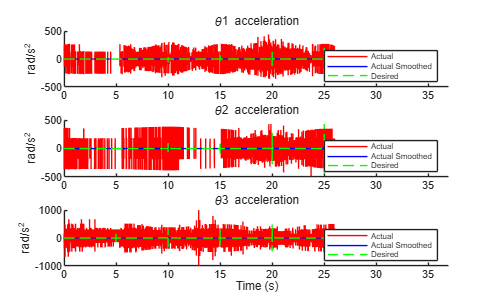



%% --- PLOTS (Acceleration) ---
figure();
subplot(3,1,1)
hold on;
plot(t, theta1_ddot_a, "red","DisplayName","Actual")
plot(t, theta1_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta1_ddot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta1 acceleration")
ylabel("rad/s^2")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, theta2_ddot_a, "red","DisplayName","Actual")
plot(t, theta2_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta2_ddot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta2 acceleration")
ylabel("rad/s^2")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, theta3_ddot_a, "red","DisplayName","Actual")
plot(t, theta3_ddot_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta3_ddot_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta3 acceleration")
ylabel("rad/s^2")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

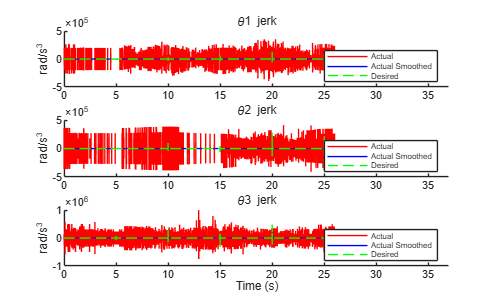


%% --- PLOTS (Jerk) ---
figure();
subplot(3,1,1)
hold on;
plot(t, theta1_jerk_a, "red","DisplayName","Actual ")
plot(t, theta1_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta1_jerk_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta1 jerk")
ylabel("rad/s^3")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize =fontsiz;
hold off;

subplot(3,1,2)
hold on;
plot(t, theta2_jerk_a, "red","DisplayName","Actual")
plot(t, theta2_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta2_jerk_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta2 jerk")
ylabel("rad/s^3")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;

subplot(3,1,3)
hold on;
plot(t, theta3_jerk_a, "red","DisplayName","Actual")
plot(t, theta3_jerk_as, "blue","DisplayName","Actual Smoothed")
plot(t, theta3_jerk_d, "green","LineStyle","--","DisplayName","Desired")
subtitle("\theta3 jerk")
ylabel("rad/s^3")
xlabel("Time (s)")
xlim([0 37])
l = legend("Location","southeast");
l.FontSize = fontsiz;
hold off;